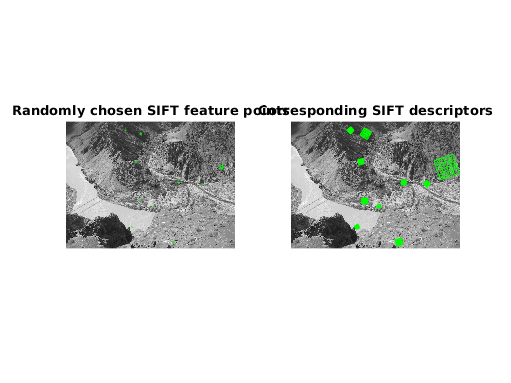

%clear all;  close all;

%VLFEATROOT = '/home/mlrosenquist/MATLAB Add-Ons/computer-vision-and-ml/vlfeat-0.9.21-bin/vlfeat-0.9.21';

%addpath('C:\Program Files\MATLAB\R2020b\toolbox');
%run([VLFEATROOT,'/toolbox/vl_setup.m']);

% Load the images (in color and grayscale)
I1rgb = imread('river1.jpg');
I1 = rgb2gray(I1rgb);
I2rgb = imread('river2.jpg');
I2 = rgb2gray(I2rgb);

% Run SIFT on image I
% Each column of F is a feature frame and has the format [X;Y;S;TH], where
% X,Y is the (fractional) center of the frame, S is the scale and TH is the
% orientation (in radians).
% Each column of D is the descriptor of the corresponding frame in F. A
% descriptor is a 128-dimensional vector of class UINT8. 
[f,d] = vl_sift(single(I1));

% Show 10 randomly chosen SIFT feature points
figure
subplot(121);
imshow(I1)
perm    = randperm(size(f,2)) ;
sel     = perm(1:10) ;
h1      = vl_plotframe(f(:,sel)) ;
set(h1,'color','g','linewidth',1) ;
title('Randomly chosen SIFT feature points')

% Show the corresponding 10 SIFT descriptors
subplot(122);
imshow(I1)
h3 = vl_plotsiftdescriptor(d(:,sel),f(:,sel)) ;
set(h3,'color','g') ;
title('Corresponding SIFT descriptors');

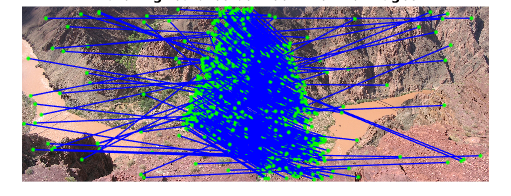


% Run SIFT on both images and find matching features
[f1, d1] = vl_sift(single(I1)) ;
[f2, d2] = vl_sift(single(I2)) ;
[matches, scores] = vl_ubcmatch(d1, d2) ;
numMatches = size(matches,2) ;

% Show matching features
% Note that there will be many false matches!
x1 = f1(1,matches(1,:)) ;
x2 = f2(1,matches(2,:)) + size(I1,2) ;
y1 = f1(2,matches(1,:)) ;
y2 = f2(2,matches(2,:)) ;
figure
imshow(cat(2, I1rgb, I2rgb)) ;
hold on ;
h = line([x1 ; x2], [y1 ; y2]) ;
set(h,'linewidth', 1, 'color', 'b','Marker','.','MarkerSize',8,'MarkerEdgeColor','g') ;
title('Matching features between the two images');

## Combine the two images

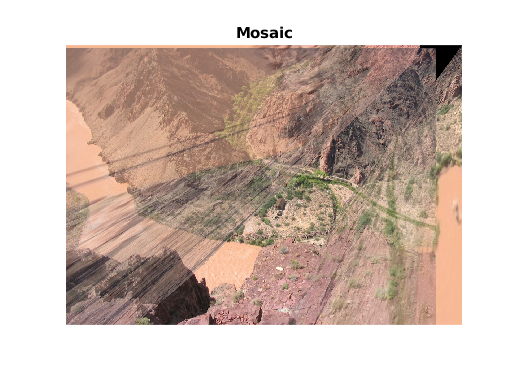

% Naive approach: use all matches to find a combined transformation
H = estimateHomography(f1,f2,matches);
showMosaic(I1rgb,I2rgb,f1,f2,matches,logical(ones(1,numMatches)),H);

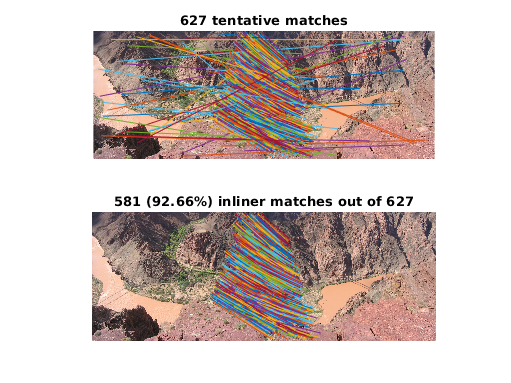

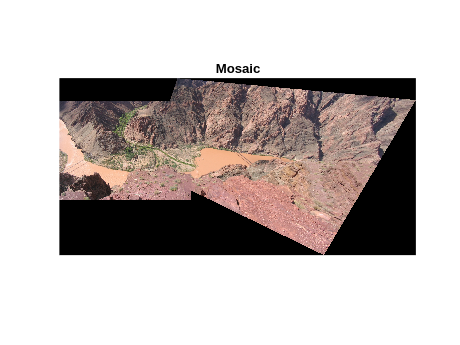

% Why does this approach not work?

% The false matches are outliers. They dominate and destroy the
% transformation estimation.
% Therefore, we have to estimate the transformation using only a subset of
% the matches (inliers - the ones that agree about a certain
% transformation)
X1 = f1(1:2,matches(1,:)) ; X1(3,:) = 1 ;
X2 = f2(1:2,matches(2,:)) ; X2(3,:) = 1 ;
clear H ok;
% We pick out random subsets of matches 100 times and choose the subset
% that fits best.
for t = 1:100
  % pick a random subset of 4 matches
  subset = vl_colsubset(1:numMatches, 4) ;
    
  % estimate homography (global transformation from I2 to I1)
  H{t} = estimateHomography(f1,f2,matches(:,subset));

  % score homography (how well do I1 and I2 fit, when they are aligned?)
  X2_ = H{t} * X1 ;
  du = X2_(1,:)./X2_(3,:) - X2(1,:)./X2(3,:) ;
  dv = X2_(2,:)./X2_(3,:) - X2(2,:)./X2(3,:) ;
  ok{t} = (du.*du + dv.*dv) < 6*6 ; % find inliers
  score(t) = sum(ok{t}) ;
end

% choose the best scoring homography
[score, best] = max(score) ;
H = H{best} ;
ok = ok{best} ;

% show mosaic
showMosaic(I1rgb,I2rgb,f1,f2,matches,ok,H);